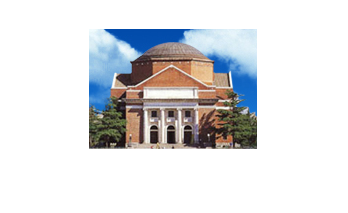

clear
clc

load('hall.mat');
imshow(hall_color);


% get size
[Height, Width] = size(hall_color, [2 1]);
% get center
h_center = (Height+1)/2;
w_center = (Width+1)/2;
% get radius
r = min(h_center, w_center);
% get index
[H, W] = meshgrid(1:Height, 1:Width);

任务a

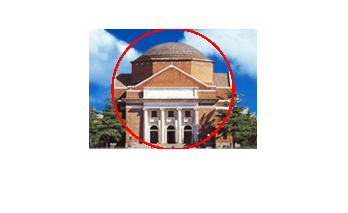

% task A
dist = sqrt((H-h_center).^2 + (W-w_center).^2);
idx = abs(dist-r)/r < 0.02;

% extract channels
red_channel = hall_color(:, :, 1); % Red channel of the image
green_channel = hall_color(:, :, 2); % Green channel of the image
blue_channel = hall_color(:, :, 3); % Blue channel of the image

% draw circle
red_channel(idx) = 255; % Set the circle region to red
green_channel(idx) = 0; % Set the green channel to 0 for the circle region
blue_channel(idx) = 0; % Set the blue channel to 0 for the circle region

% merge
circ_hall = cat(3, red_channel, green_channel, blue_channel);

% Display the image with the red circle
imshow(circ_hall);

% imwrite(circ_hall,'circ_hall.bmp');

任务b

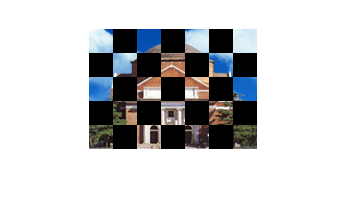

% task B
w_flag = mod(floor((W-1)/24),2);
h_flag = mod(floor((H-1)/24),2);
mask = xor(w_flag, h_flag);

% extract channels
red_channel = hall_color(:, :, 1); % Red channel of the image
green_channel = hall_color(:, :, 2); % Green channel of the image
blue_channel = hall_color(:, :, 3); % Blue channel of the image

% draw chessboard
red_channel(mask) = 0;
green_channel(mask) = 0;
blue_channel(mask) = 0;

% merge
chessboard_hall = cat(3, red_channel, green_channel, blue_channel);

% display
imshow(chessboard_hall);

% imwrite(chessboard_hall,'chessboard_hall.bmp','bmp');